# Derive Path Using a Probabilistic Road Map

Copyright 2021 The MathWorks, Inc

This script shows how use a Probabilistic Road Map (PRM) algorithm to derive a path of cartesian points that connect a start location with a target location while avoiding the artifacts included in the occupancy map.

For more information on PRM algorithms visit the respective [MATLAB® documentation page.](https://www.mathworks.com/help/robotics/ug/probabilistic-roadmaps-prm.html)

load('turtleBotMazeMap.mat')

% Definte start and end goals
startPose = [0 0];
endPose = [0 3.8];
% Inflate map to account for robot size
inflate(myOccMap,0.29/2)

% Create PRM object
prm = mobileRobotPRM(myOccMap,50);
path = findpath(prm,startPose,endPose)

path =          0         0
    0.1123   -0.1092
    1.3152    0.2174
    0.1118    1.1599
    0.1198    4.0806
         0    3.8000


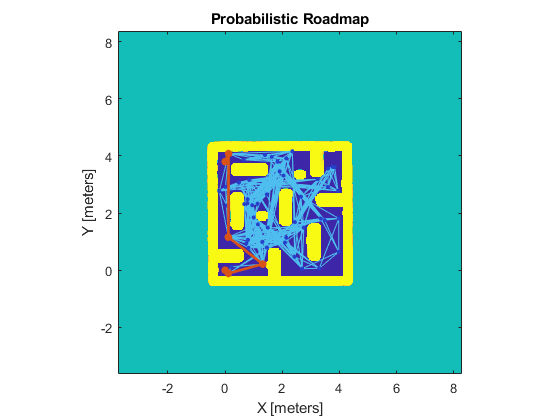

show(prm)